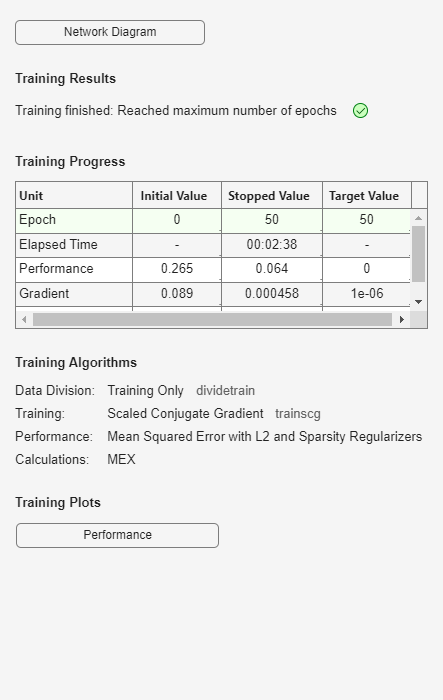

clc;
clear;
close all;

% Load MNIST Dataset
train_data = readmatrix('mnist_train.csv');
test_data = readmatrix('mnist_test.csv');

% Separate labels and pixel values
train_labels = train_data(:, 1);
train_images = train_data(:, 2:end);
test_labels = test_data(:, 1);
test_images = test_data(:, 2:end);

% Normalize pixel values to [0, 1]
train_images = double(train_images) / 255;
test_images = double(test_images) / 255;

% Reshape data for autoencoder (columns are samples)
train_images = train_images';
test_images = test_images';

% Define and Train Autoencoder
hiddenSize = 64; % Size of the bottleneck layer
autoenc = trainAutoencoder(train_images, ...
    'MaxEpochs', 50, ...
    'L2WeightRegularization', 0.001, ...
    'SparsityRegularization', 4, ...
    'SparsityProportion', 0.05);


% Define SNR levels for evaluation
snr_levels = 1:10; % SNR in dB
num_samples = 10;  % Number of test samples for visualization
psnr_results = struct('Autoencoder', [], 'JPEG', [], 'DeepJSCC', []);

% Loop through each SNR level
for snr_idx = 1:length(snr_levels)
    snr = snr_levels(snr_idx);

    % Initialize PSNR values
    psnr_autoencoder = 0;
    psnr_jpeg = 0;
    psnr_deepjscc = 0;

    for i = 1:num_samples
        % Step 1: Original Image
        img = test_images(:, i);
        img_reshaped = reshape(img, 28, 28);

        % Step 2: Autoencoder Reconstruction
        encoded_test_data = encode(autoenc, test_images); % Encode
        flat_data = encoded_test_data(:);

        % Apply fading channel
        fading_coeff = (randn(size(flat_data)) + 1i * randn(size(flat_data))) / sqrt(2); % Rayleigh fading
        noisy_signal = fading_coeff .* flat_data;
        noisy_signal = awgn(noisy_signal, snr, 'measured'); % Add Gaussian noise
        received_signal = noisy_signal ./ fading_coeff; % Equalize fading
        received_encoded_data = reshape(real(received_signal), size(encoded_test_data));
        reconstructed_autoencoder = decode(autoenc, received_encoded_data);
        reconstructed_autoencoder = reshape(reconstructed_autoencoder(:, i), 28, 28);

        % Calculate PSNR for Autoencoder
        psnr_autoencoder = psnr_autoencoder + psnr(reconstructed_autoencoder, img_reshaped);

        % Step 3: JPEG Reconstruction
        img_uint8 = im2uint8(img_reshaped); % Convert to uint8 for JPEG
        imwrite(img_uint8, 'temp.jpg', 'Quality', round(100 - snr * 10)); % Adjust JPEG quality
        jpeg_img = im2double(imread('temp.jpg'));
        % Pass JPEG image through fading channel
        jpeg_flat = jpeg_img(:);
        fading_coeff_jpeg = (randn(size(jpeg_flat)) + 1i * randn(size(jpeg_flat))) / sqrt(2); % Rayleigh fading
        noisy_signal_jpeg = fading_coeff_jpeg .* jpeg_flat;
        noisy_signal_jpeg = awgn(noisy_signal_jpeg, snr, 'measured'); % Add Gaussian noise
        received_jpeg_signal = noisy_signal_jpeg ./ fading_coeff_jpeg; % Equalize fading
        jpeg_img_reconstructed = reshape(real(received_jpeg_signal), size(jpeg_img));

        % Calculate PSNR for JPEG
        psnr_jpeg = psnr_jpeg + psnr(jpeg_img_reconstructed, img_reshaped);

        % Step 4: DeepJSCC Reconstruction
        noisy_encoded_deepjscc = encoded_test_data + randn(size(encoded_test_data)) * 0.1; % Add Gaussian noise
        flat_deepjscc = noisy_encoded_deepjscc(:);
        fading_coeff_deepjscc = (randn(size(flat_deepjscc)) + 1i * randn(size(flat_deepjscc))) / sqrt(2); % Rayleigh fading
        noisy_signal_deepjscc = fading_coeff_deepjscc .* flat_deepjscc;
        noisy_signal_deepjscc = awgn(noisy_signal_deepjscc, snr, 'measured'); % Add Gaussian noise
        received_deepjscc_signal = noisy_signal_deepjscc ./ fading_coeff_deepjscc; % Equalize fading
        deepjscc_reconstructed = reshape(real(received_deepjscc_signal), size(noisy_encoded_deepjscc));
        deepjscc_reconstructed = decode(autoenc, deepjscc_reconstructed);
        deepjscc_reconstructed = reshape(deepjscc_reconstructed(:, i), 28, 28);

        % Calculate PSNR for DeepJSCC
        psnr_deepjscc = psnr_deepjscc + psnr(deepjscc_reconstructed, img_reshaped);
    end

    % Average PSNR for each method
    psnr_results.Autoencoder(end + 1) = psnr_autoencoder / num_samples;
    psnr_results.JPEG(end + 1) = psnr_jpeg / num_samples;
    psnr_results.DeepJSCC(end + 1) = psnr_deepjscc / num_samples;

    % Display Results at Current SNR
    fprintf('SNR: %d dB | PSNR (Autoencoder): %.2f | PSNR (JPEG): %.2f | PSNR (DeepJSCC): %.2f\n', ...
        snr, psnr_results.Autoencoder(end), psnr_results.JPEG(end), psnr_results.DeepJSCC(end));
end

SNR: 1 dB | PSNR (Autoencoder): 12.73 | PSNR (JPEG): 6.00 | PSNR (DeepJSCC): 13.07
SNR: 2 dB | PSNR (Autoencoder): 13.06 | PSNR (JPEG): 5.88 | PSNR (DeepJSCC): 12.91
SNR: 3 dB | PSNR (Autoencoder): 13.15 | PSNR (JPEG): 8.42 | PSNR (DeepJSCC): 13.06
SNR: 4 dB | PSNR (Autoencoder): 13.07 | PSNR (JPEG): 8.91 | PSNR (DeepJSCC): 13.00
SNR: 5 dB | PSNR (Autoencoder): 12.96 | PSNR (JPEG): 9.70 | PSNR (DeepJSCC): 12.96
SNR: 6 dB | PSNR (Autoencoder): 13.01 | PSNR (JPEG): 10.55 | PSNR (DeepJSCC): 13.10
SNR: 7 dB | PSNR (Autoencoder): 13.05 | PSNR (JPEG): 11.03 | PSNR (DeepJSCC): 13.12
SNR: 8 dB | PSNR (Autoencoder): 13.05 | PSNR (JPEG): 13.08 | PSNR (DeepJSCC): 13.11
SNR: 9 dB | PSNR (Autoencoder): 13.11 | PSNR (JPEG): 13.50 | PSNR (DeepJSCC): 13.15
SNR: 10 dB | PSNR (Autoencoder): 13.09 | PSNR (JPEG): 13.27 | PSNR (DeepJSCC): 13.03


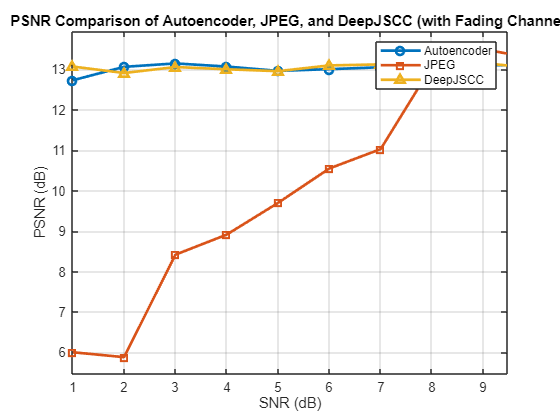


% Step 5: Plot PSNR Results
figure;
plot(snr_levels, psnr_results.Autoencoder, '-o', 'LineWidth', 2);
hold on;
plot(snr_levels, psnr_results.JPEG, '-s', 'LineWidth', 2);
plot(snr_levels, psnr_results.DeepJSCC, '-^', 'LineWidth', 2);
grid on;
xlabel('SNR (dB)');
ylabel('PSNR (dB)');
title('PSNR Comparison of Autoencoder, JPEG, and DeepJSCC (with Fading Channel)');
legend('Autoencoder', 'JPEG', 'DeepJSCC');